# **drawHyperbola**

Draw the arc of hyperbola

## Description

 Parametric equation of the hyperbola is

$x=a\;\mathrm{cosh}\;t$,     $y=b\;\mathrm{sinh}\;t$,    $-\infty <t<\infty$.

where a*, *b* are semi axes*.

## Syntax

drawHyperbola( t1, t2, a, b, xc, yc)

drawHyperbola( t1, t2, a, b, xc, yc, rot)

drawHyperbola( t1, t2, a, b, '-np', np)

drawHyperbola( t1, t2, a, b, LineSpec)

p = drawHyperbola(__)

## Description

drawHyperbola( t1, t2, a, b,xc,yc) draw the arc with default number of points 360 and current line specification. 

drawHyperbola( t1, t2, a, b, xc, yc, rot) rotated by the angle *rot *in CCLW direction around center. 

drawHyperbola( __, LineSpec)  sets the line style, line width, and color.

drawHyperbola( __,'-np',np) set the number of points on the output curve.

p = drawHyperbola(__) returns structure with output data.

## Method

For calculation of the coordinates of the curve **drawHyperbola **call function **evalHyperbola(a, b,xc,yc,rot,t)  **which returns coordinates *x *and *y *of the curve at given parameters t . For usage of **evalHyperbola **see Example 1.

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**t1 **- initial parameter

**t2 **- final parameter

**a **- focal distance (real scalar)

**b **- focal distance (real scalar)

**xc - **x-coordinate of the center (real scalar)

**yc **- y-coordinate of the center (real scalar)

### **Optional Input Argumnts**

**rot** - rotation angle about the center in degrees

**'-pie'|'-seg'** - draw pie or segment

### Optional Name-Value Pair Input Arguments

**'-np',** **np **- number of points along the curve ( scalar integer value > 2)

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with the fields

- p.xk, p.yk - key points: 1=start,2=end,3=center

- p.th - tangent angle: 1=start,2=end 

- p.color - line color

## Examples

### Example 1

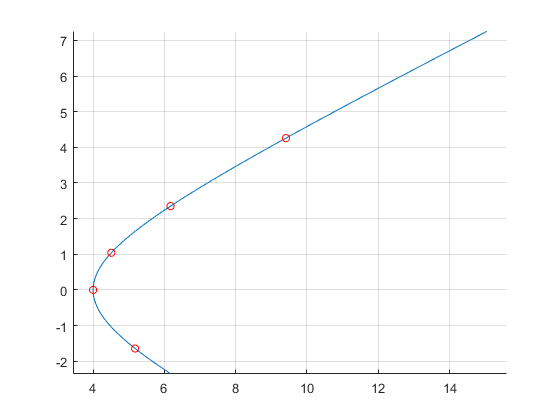

%Data 
a = 4;
b = 2;
% plot
figure
hold on
axis equal
[x,y] = evalHyperbola(a, b,0,0,0,linspace(-1,2));
plot(x,y)
[x,y] = evalHyperbola(a, b,0,0,0,[-0.75, 0, 0.5,1, 1.5]);
scatter(x,y,30,'r')
grid on

### Example 2

%Data 
xc = -1;
yc = 2;
a = 4;
b = 2;
t1 = -1;
t2 = 1.5;
figure
hold on
axis equal
H1 = drawHyperbola(t1,t2,a,b,1,1,'-seg')

H1 = struct with fields:
       xk: [7.1723 10.4096 1]
       yk: [-1.3504 5.2586 1]
       th: [146.7144 28.9161]
    color: 'k'


H2 = drawHyperbola(t1,t2,a,b,xc,yc,45,'-sec','LineWidth',2,'Color','r','-np',10)

H2 = struct with fields:
       xk: [5.0265 2.6424 -1]
       yk: [4.7025 11.6649 2]
       th: [191.7144 73.9161]
    color: [1 0 0]


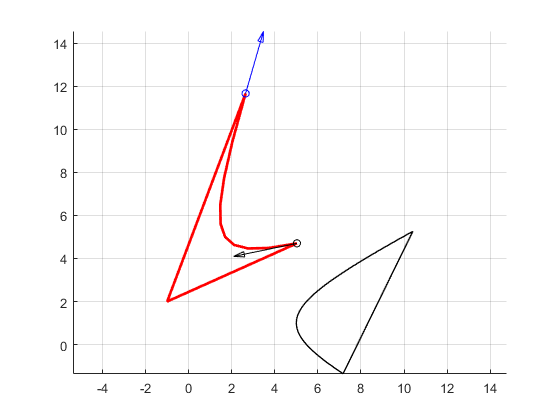

scatter(H2.xk(1),H2.yk(1),30,'k')
scatter(H2.xk(2),H2.yk(2),30,'b')
drawArrow(2,0.5,0.25,H2.xk(1),H2.yk(1),'-rtheta',3,H2.th(1),'k')
drawArrow(2,0.5,0.25,H2.xk(2),H2.yk(2),'-rtheta',3,H2.th(2),'b')
grid on

### Example 3

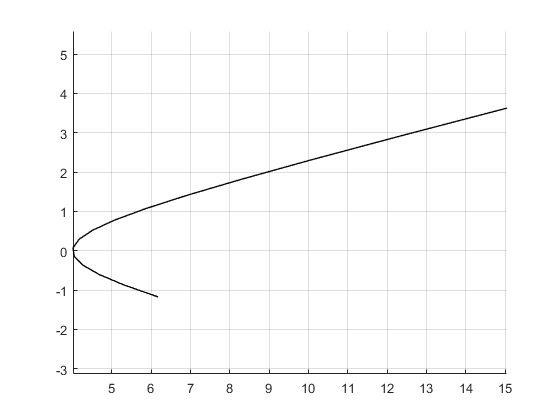

figure
hold on
axis equal
drawHyperbola(2,-1,4,1,0,0,'-np',15)
grid on

## **See Also**

## References